BackTestV2

clear
tic

T = readtable("Trend Trading Input Output Data.xlsx", "Sheet","Price Data");

PriceTTraw = table2timetable (T) ;

PriceTTSemiClean = fillmissing (PriceTTraw, "previous") ;
PriceTT = fillmissing (PriceTTSemiClean, "next") ;

%SMA Signal
LeadDays = 2 ; 
LagDays = 20 ;

SMALead = movavg (PriceTT, 'simple', LeadDays) ;
SMALag = movavg (PriceTT, 'simple', LagDays) ;

SMASignalTT = PriceTT ;
SMASignalTT.Variables = SMALead.Variables > 1 * SMALag.Variables ;
SMASignalFinalTT = SMASignalTT ;
SMASignalFinal = SMASignalFinalTT.Variables ;
SMASignal = SMASignalTT.Variables ;
SMASignalFinal (2:end, :) = SMASignal (1:end-1, :) ;
SMASignalFinal (1, :) = 0 ;
SMASignalFinalTT.Variables = SMASignalFinal

SMASignalFinalTT = 2859×665 timetable
       Time        ANTM    ANJT    ANDI    AMRT    AMOR    AMIN    AMFG    AMAR    AMAN    AISA    AIMS    AHAP    AGRS    AGRO    AGII    AGAR    ADRO    ADMG    ADMF    ADHI    ADES    ACST    ACES    ABMM    ABDA    ABBA    AALI    AMAG    ALTO    ALMI    ALKA    ALDO    AKSI    AKRA    AKPI    AKKU    DLTA    <

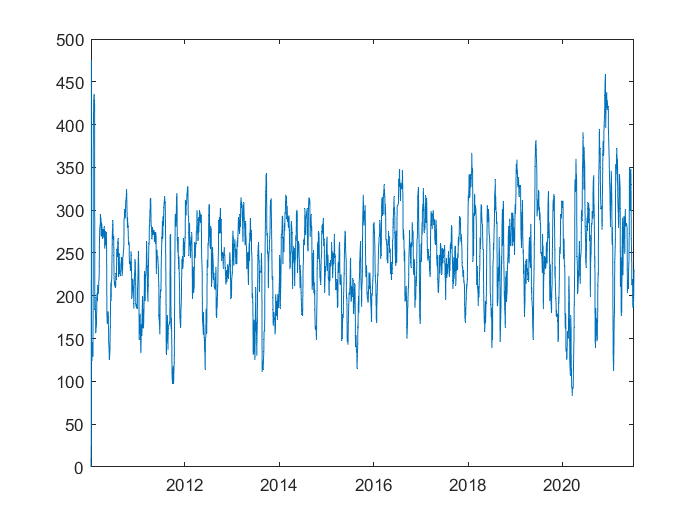


nDailySignal = sum(SMASignalFinal,2) ;
nDailySignalTT = timetable (SMASignalFinalTT.Time, nDailySignal, 'VariableNames',"nDailySignal") ;
plot (nDailySignalTT.Time, nDailySignalTT.Variables )


%Strategy
TradingCosts = [0.2/100, 0.2/100] ;

SMAInitWeights = [] ;
SMArebalanceFcn = @RebalanceWeightsFcn ;
SMAStrategy = backtestStrategy ('SMAStrategyBacktest', SMArebalanceFcn, ...
    'TransactionCosts',TradingCosts, "RebalanceFrequency", 1, ...
    "LookbackWindow", 2, "InitialWeights",SMAInitWeights ) 

SMAStrategy =   backtestStrategy with properties:

                  Name: "SMAStrategyBacktest"
          RebalanceFcn: @RebalanceWeightsFcn
    RebalanceFrequency: 1
      TransactionCosts: [0.0020 0.0020]
        LookbackWindow: 2
        InitialWeights: [1×0 double]



%Set-up backtest engine
bt = backtestEngine(SMAStrategy, 'RiskFreeRate', 0.0/365, ...
    "InitialPortfolioValue", 10^9)

bt =   backtestEngine with properties:

               Strategies: [1×1 backtestStrategy]
             RiskFreeRate: 0
           CashBorrowRate: 0
    InitialPortfolioValue: 1.0000e+09
                NumAssets: []
                  Returns: []
                Positions: []
                 Turnover: []
                  BuyCost: []
                 SellCost: []



% run the strategy backtest
startIdx = max(LeadDays, LagDays) ;

bt = runBacktest (bt, PriceTT, SMASignalFinalTT, 'start', startIdx) 

Error using backtestStrategy
Expected Weights to be a vector.

Error in backtestStrategy/set.Weights (line 263)
            validateattributes(value,"numeric","vector",mfilename,"Weights");

Error in backtestStrategy/rebalance (line 286)
                obj.Weights = obj.

% Summary
SummaryTable = summary (bt)
%Plot cumulative return
dailyRet = bt.Returns ;
portfolioValue = ret2tick (dailyRet) ;
plot (portfolioValue.Time, portfolioValue.Variables)

%Asset area plot
time = bt.Positions.SMAStrategyBacktest.Time ;
positions = bt.Positions.SMAStrategyBacktest.Variables ;

Period = yearfrac (time(1), time(end))
PortValue = portfolioValue.Variables ;
portfolioValue (end,:)
CAGR = (PortValue (end))^(1/Period)-1

PositionsTT = bt.Positions.SMAStrategyBacktest ;
InitialWeightsTT = bt.Strategies.InitialWeights ;

outputFilename = 'Output3.xlsx' ;
writetimetable (PositionsTT, outputFilename, 'sheet', "PositionsTT") ;
% writematrix (InitialWeightsTT , outputFilename, 'sheet', "InitialWeightsTT") ;


% h = area (time, positions)

% assetAreaPlot (bt, 'SMAStrategyBacktest')

toc

Local functions

function CapAlloc = ComputeWeights (SignalTT) 
% Compute weights based on most recent signal.

Signals = SignalTT.Variables ;
nInvestableAssets = sum (Signals(end, :), 2) ;

CapAlloc = Signals(end, :)/nInvestableAssets ;
CapAlloc (isinf (CapAlloc)) = 0 ;

end

function new_weights = RebalanceWeightsFcn (Current_Weights,PriceTT , SignalTT) 
% Compute weights based on most recent signal.

% Pull out the signal
CrossoverSignal = SignalTT.Variables ;

% Start with current weights
new_weights = Current_Weights ;

% Sell existing long positions where the signal has turned from 1 to 0
idx = CrossoverSignal(end,:) == 0 ;
new_weights (idx) = 0 ;

% Find new crossover (signal has turned from 0 to 1)
idx = CrossoverSignal (end,:) == 1 ;
new_weights (idx) = 0 ;

% Bet sizing
UninvestedAssets = sum (CrossoverSignal(end, :)) ;
new_weights (idx) = CrossoverSignal(idx) ./ UninvestedAssets ;


end

function InitialWeights = ComputeInitialWeights (SignalTT) 
% Compute initial weights based on most recent signal.

Signals = SignalTT.Variables ;
nAssets = size (Signals, 2) ;
FinalSignal = Signals (end, :) ;
buys = FinalSignal == 1 ;
InitialWeights = zeros (1, nAssets) ;
InitialWeights (buys) = 1/nAssets ;

end


function new_weights = CrossoverRebalanceFcn (Current_Weights, SignalTT) 
% Signal crossover rebalance function.

% Pull out the signal
CrossoverSignal = SignalTT.Variables ;

% Start with current weights
new_weights = Current_Weights ;

% Sell existing long positions where the signal has turned from 1 to 0
idx = CrossoverSignal(end,:) == 0 ;
new_weights (idx) = 0 ;

% Find new crossover (signal has turned from 0 to 1)
idx = and (CrossoverSignal (end-1,:) == 0, CrossoverSignal (end,:) == 1 ) ;

% Bet sizing
AvailableCapital = 1 - sum (new_weights) ;
UninvestedAssets = 1 - sum (new_weights == 0) ;
new_weights (idx) = AvailableCapital / UninvestedAssets ;

end
